clear; close all; clc;
rng(41137)

# 1 SYSTEM MODEL AND GENERATION OF QAM SYMBOLS

## 1.1 SYSTEM MODEL

### 1.2 CONSIDERED SYSTEM PARAMETERS

alphabet_size = 16;  
% Number of symbols in the QAM alphabet (e.g. 16 means 16-QAM). Valid alphabet 
% sizes are 4, 16, 64, 256, 1024, ... (i.e. the possible values are given 
% by the vector 2.^(2:2:N), for any N) 
 
SNR = 25;                   % Signal-to-noise power ratio [dB] 
T = 1/10e6;                 % Symbol time interval [s] 
fc = 75e6;                  % Carrier frequency 
r = 20;                     % Oversampling factor (r samples per pulse) 
N_symbols_per_pulse = 30;   % Duration of TX/RX-filters in numbers of symbols 
alfa = 0.25;                % Roll-off factor (excess bandwidth

Fs = r/T;               % Sampling frequency 
Ts = 1/Fs;              % Sampling time interval

N_data_symbols = 10000;      % Number of data symbols 
N_training_symbols = 940;    % Number of training symbols

### 1.3 GENERATION OF QAM SYMBOLS AND THE TRANSMITTED SYMBOL FRAME

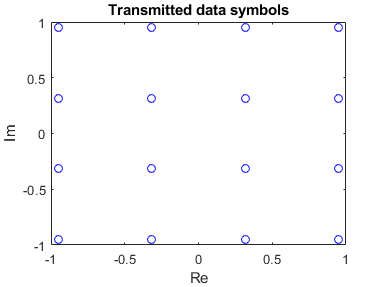

% Here qam_axis presents the symbol values in real/imaginary axis. So, 
%generally for different alphabet/constellation sizes (): 
qam_axis = -sqrt(alphabet_size)+1:2:sqrt(alphabet_size)-1; 
% For example, the above results in 
% qam_axis = [-1 1];                % for QPSK 
% qam_axis = [-3 -1 1 3];           % for 16-QAM 
% qam_axis = [-7 -5 -3 -1 1 3 5 7]; % for 64-QAM 
 
% generation of a complex constellation: 
alphabet = bsxfun(@plus,qam_axis',1j*qam_axis); %help bsxfun 
%%% equivalent to alphabet = repmat(qam_axis', 1, sqrt(alphabet_size)) + 
repmat(1j*qam_axis, sqrt(alphabet_size), 1); %%% 
alphabet = alphabet(:).'; % alphabet symbols as a row vector 
 
% Scaling the constellation, so that the mean power of a transmitted symbol 
% is one (e.g., with QPSK this is 1/sqrt(2), and for 16-QAM 1/sqrt(10)) 
alphabet_scaling_factor = 1/sqrt(mean(abs(alphabet).^2)); 
alphabet = alphabet*alphabet_scaling_factor; 
 
% Random vector of symbol indices (i.e., numbers between 1...alphabet_size) 
symbol_ind = randi(length(alphabet),1,N_data_symbols);  
 
data_symbols = alphabet(symbol_ind); % Data symbols to be transmitted 
 
figure 
plot(data_symbols,'bo') 
xlabel('Re') 
ylabel('Im') 
title('Transmitted data symbols')


% Generation of training symbols (similar to data symbols): 
training_symbols = alphabet(randi(length(alphabet),1,N_training_symbols)); 
 
% Concatenating the training and data symbols to get the overall 
% transmitted symbols: 
symbol_frame = [training_symbols data_symbols];

## 2 TRANSMITTER STRUCTURE

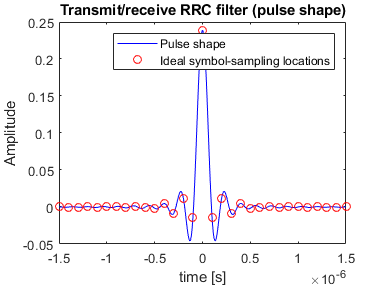

p = rcosdesign(alfa,N_symbols_per_pulse,r,'sqrt'); 
figure 
plot(-N_symbols_per_pulse*r/2*Ts:Ts:N_symbols_per_pulse*r/2*Ts,p,'b') 
hold on 
plot(-N_symbols_per_pulse*r/2*Ts:T:N_symbols_per_pulse*r/2*Ts,p(1:r:end),'ro') 
xlabel('time [s]') 
ylabel('Amplitude') 
title('Transmit/receive RRC filter (pulse shape)') 
legend('Pulse shape','Ideal symbol-sampling locations')


%%Filter transmitted symbol frame
symbols_upsampled = zeros(size(1:r*length(symbol_frame)));    % Zero vector 
% initilized for Up-sampled symbol sequence 
symbols_upsampled(1:r:r*length(symbol_frame)) = symbol_frame; 
% I.e. now the up-sampled sequence looks like {a1 0 0... a2 0 0... a3 0 0...} 
x_LP = filter(p,1,symbols_upsampled); % Transmitter filtering 
x_LP = x_LP(1+(length(p)-1)/2:end); % Filter delay correction 
%notice the here x_LP is the complex-valued lowpass equivalent signal of the 
% transmitted real-valued bandpass signal x_BP (generated in the next stage)

## 5 TIMING: Modifying TX structure based on asynchronized time clock

% Time vector for the RX oscillator signal: 
TX_clock_start_time = rand; % Clock start time in the TX oscillator 

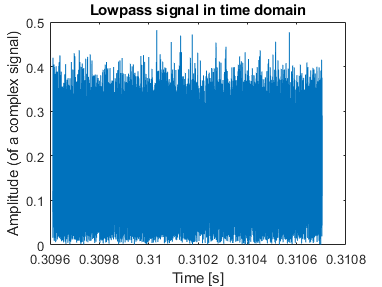

%%Implement the upconversion (modulation / frequency translation to the carrier frequency fc)
% Time vector for the TX oscillator signal: 
t_TX_oscillator = TX_clock_start_time + (0:Ts:Ts*(length(x_LP)-1)); 
% TX oscillator signal: 
TX_oscillator_signal = exp(1j*2*pi*fc*t_TX_oscillator); 
% Carrier modulation / upconversion (still complex valued): 
x_BP_complex = x_LP.*TX_oscillator_signal;

% Taking the real value to finalize the lowpass-to-bandpass transformation: 
x_BP = sqrt(2)*real(x_BP_complex);

%%PLOTING
figure % zoom manually to see the signal better 
plot(t_TX_oscillator, abs(x_LP)) 
xlabel('Time [s]') 
ylabel('Amplitude (of a complex signal)') 
title('Lowpass signal in time domain') 

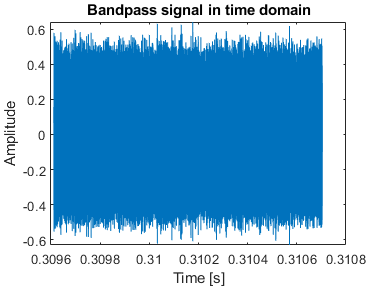

 
figure % zoom manually to see the signal better 
plot(t_TX_oscillator, x_BP) %notice no abs needed 
xlabel('Time [s]')
ylabel('Amplitude') 
title('Bandpass signal in time domain')

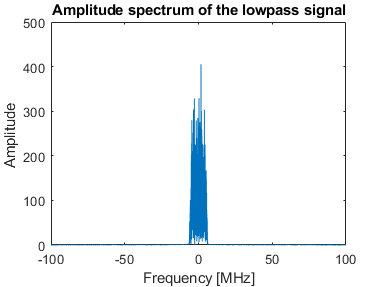


NFFT = 2^14; %FFT size 
f = -Fs/2:1/(NFFT*Ts):Fs/2-1/(NFFT*Ts);%frequency vector

figure 
plot(f/1e6, fftshift(abs(fft(x_LP,NFFT)))) 
xlabel('Frequency [MHz]') 
ylabel('Amplitude ') 
title('Amplitude spectrum of the lowpass signal') 

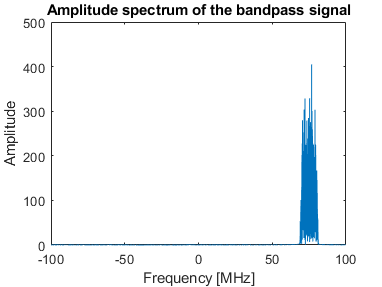

 
figure 
plot(f/1e6, fftshift(abs(fft(x_BP_complex,NFFT)))) %notice no abs needed 
xlabel('Frequency [MHz]') 
ylabel('Amplitude') 
title('Amplitude spectrum of the bandpass signal') 

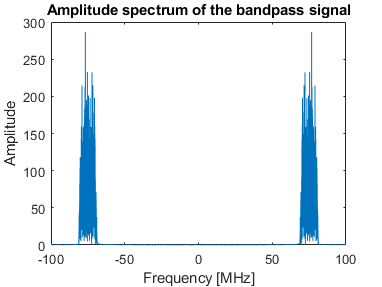

 
figure 
plot(f/1e6, fftshift(abs(fft(x_BP,NFFT)))) %notice no abs needed 
xlabel('Frequency [MHz]') 
ylabel('Amplitude') 
title('Amplitude spectrum of the bandpass signal')

## 5 ADD DElAY to AWGN

delay = randi(940) % Delay in samples 

delay = 733

x_BP = [zeros(1,delay), x_BP]; % & Add %delay  zeros

## 3 CHANNEL MODEL 

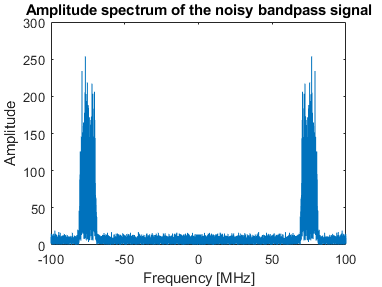

%%generate Noise
n = randn(size(x_BP));       % White Gaussian random noise 
P_x_BP = var(x_BP); % Signal power 
P_n = var(n); % Noise power            
% Defining noise scaling factor based on the desired SNR: 
noise_scaling_factor = sqrt(P_x_BP/P_n/10^(SNR/10)*(r/(1+alfa)));
% Noisy signal 
y_BP = x_BP + noise_scaling_factor*n;

%%plot noisy band-pass signal
figure 
plot(f/1e6, fftshift(abs(fft(y_BP,NFFT)))) %notice no abs needed 
xlabel('Frequency [MHz]') 
ylabel('Amplitude') 
title('Amplitude spectrum of the noisy bandpass signal')

## 4 RECEIVER STRUCTURE

## 4.1 DOWNCONVERSION AND SIGNAL FILTERING

## 5 TIMING: Modifying RX oscillator signal based on asynchronized clock time

RX_clock_start_time = rand; % Clock start time in the RX oscillator

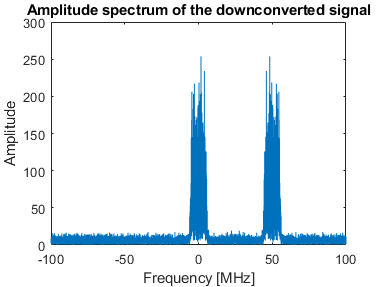

% Time vector for the RX oscillator signal: 
t_RX_oscillator = RX_clock_start_time + (0:Ts:Ts*(length(y_BP)-1)); 
% RX oscillator signal (notice the minus-sign compared to TX oscillator!!!):

RX_oscillator_signal = exp(-1j*2*pi*fc*t_RX_oscillator); 
% Carrier demodulation / downconversion (signal becomes complex again) 
y_BP_downconverted = y_BP.*RX_oscillator_signal;

figure 
plot(f/1e6, fftshift(abs(fft(y_BP_downconverted,NFFT)))) %notice no abs needed 
xlabel('Frequency [MHz]') 
ylabel('Amplitude') 
title('Amplitude spectrum of the downconverted signal')

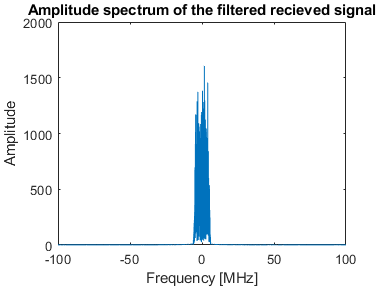


%%Filter recieved signal
X_LP_received = sqrt(2)*filter(p,1,y_BP_downconverted); % Receiver filtering  
X_LP_received = X_LP_received(1+(length(p)-1)/2:end); %Filter delay correction

figure 
plot(f/1e6, fftshift(abs(fft(X_LP_received,NFFT)))) %notice no abs needed 
xlabel('Frequency [MHz]') 
ylabel('Amplitude') 
title('Amplitude spectrum of the filtered recieved signal')

## 5.1 TIMING SYNCHRONIZATION based on Training signal

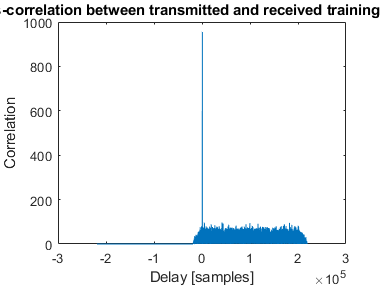

training_signal = zeros(size(1:r*length(training_symbols)));    % Zero vector 
% initilized for Up-sampled symbol sequence 
training_signal(1:r:r*length(training_symbols)) = training_symbols; 
% I.e. now the up-sampled sequence looks like {a1 0 0 a2 0 0 a3 0 0 a4 0 ...}

% Calculate the cross-correlation 
[corr_fun, delay] = xcorr(X_LP_received,training_signal); %cross-correlation

figure 
plot(delay,abs(corr_fun)) 
xlabel('Delay [samples]') 
ylabel('Correlation') 
title('Cross-correlation between transmitted and received training symbols')


% Find the sample index with the maximum correlation value: 
[~, max_ind] = max(abs(corr_fun)); 
 
%Estimated delay: The 1st signal sample should be taken at "timing_ind+1" 
timing_ind = delay(max_ind); 

RX_symbol_frame = X_LP_received(timing_ind+1:r:end);

### 4.2 SIGNAL SAMPLING

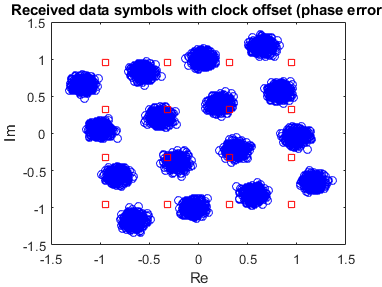

% Sampling the received signal in order to get symbol samples 

%%%%%%%%RX_symbol_frame = X_LP_received(1:r:end)%%%%%%%%%%%;

%%seperating training & data symbols
RX_training_symbols = RX_symbol_frame(1:N_training_symbols); 
RX_data_symbols = RX_symbol_frame(N_training_symbols+1:end);

figure 
plot(RX_data_symbols,'bo') 
hold on 
plot(alphabet,'rs') 
hold off 
xlabel('Re') 
ylabel('Im') 
title('Received data symbols with clock offset (phase error)')

### 5.2 PHASE ERROR ESTIMATION AND PHASE COMPENSATION

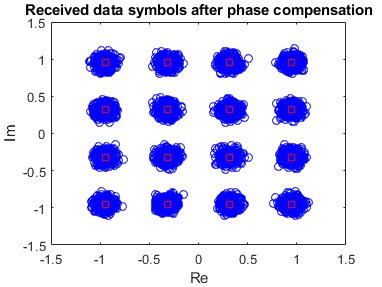


% Here RX_training_symbols and training_symbols should be row-vectors 
channel_estimate = ... %with 3 dots the expression continues on the next line 
    RX_training_symbols*training_symbols'/norm(training_symbols)^2; %help norm 

RX_data_symbols_phase_compensation = RX_data_symbols/channel_estimate;

figure 
plot(RX_data_symbols_phase_compensation,'bo') 
hold on 
plot(alphabet,'rs') 
hold off 
xlabel('Re') 
ylabel('Im') 
title('Received data symbols after phase compensation')

### 4.3 OBTAINING SYMBOL DECISIONS AND CALCULATING THE SYMBOL ERROR RATE (SER)

alphabet_error_matrix = abs(bsxfun(@minus,alphabet.',RX_data_symbols)); 
% Now, rows represent the alphabet symbol indices and columns represent the 
% received symbol indices (e.g. the Euclidian distance between the 5th 
% received symbol and the 3rd symbol in the alphabet is given as 
% "alphabet_error_matrix(3,5)"
[~,estimated_symbol_ind] = min(alphabet_error_matrix);

% Finding out which symbols were estimated incorrecly: 
symbol_errors = ... 
    estimated_symbol_ind ~= symbol_ind(1:length(estimated_symbol_ind));
% notice that due to filtering transitions, we lose some of the last 
% symbols in the symbol frame. In practice we would simply continue taking 
% a few samples after the frame to try to get all the symbols. However, filter 
% transitions in the beginning and in end of the frame are always creating 
% non-idealities to the transmission (the same is also happening in 
% frequency domain: e.g. compare data in the middle and in the edge of 
% the used band). 

 

% Symbol Error Rate (SER) (0 means 0% of errors, 1 means 100% of errors) 
SER = mean(symbol_errors)

SER = 1


%Try the above code 
% by altering the SNR and the QAM constellation size (QPSK, 64-QAM, etc.)
%Done by adding control box in the parameter setting 